# **Symbolic distributed parameter model**

**2023-08-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

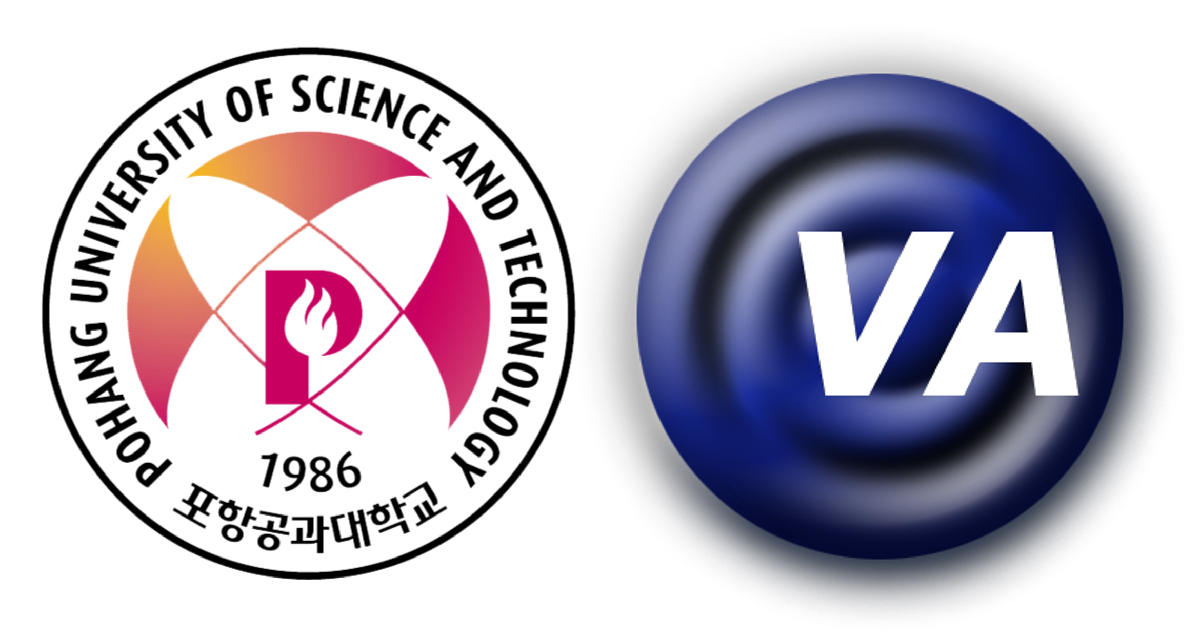

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

% Load the material properties
mat = import_material('materials_OBS_loss_D.txt');
mat.Y33D('C-21') = mat.Y33('C-21')/(1-mat.k33('C-21')^2);
mat.v3D('C-21') = sqrt(mat.Y33D('C-21')/mat.rho('C-21'));

% Load the plate's impedance
[~,Z_p_wo_steps] = import_impedance('D -230725 - Stepped-plate impedance w.o. steps.txt');
[~,Z_p_w_steps] = import_impedance('D -230725 - Stepped-plate impedance w. steps.txt');

% Define the structure
nStart = 1;    % Start index of node;
nEnd   = 5;    % End index of node;
if nStart > nEnd
    disp("Error: the end index of node must be greater than start index!");
    return
end
eCount    = nEnd - nStart;
nCount    = eCount+1;
S = sprintf("The number of elements:    %d\n" + "The number of nodes:       %d",eCount,nCount);
disp(S);

The number of elements:    4
The number of nodes:       5


ePiezo = 2;  % Index of piezoelectric bar

## Initialize symbols

% for material properties and design parameters of elements
% Frequency
syms freq

% Mechanical
rho = sym('rho_%d', [1 nEnd]); % Density
E   = sym('E_%d',   [1 nEnd]); % Young's modulus
c   = sym('c_%d',   [1 nEnd]); % Longitudinal wave speed
k   = sym('k_%d',   [1 nEnd]); % Longitudinal wave number
l   = sym('l_%d',   [1 nEnd]); % Length of element
A   = sym('A_%d',   [1 nEnd]); % Area of element
Z   = sym('Z_%d',   [1 nEnd]); % Acoustical impedance of bar
Z_p = sym('Z_p');               % Mehcanical impedance of plate

% Electircal
syms Z0;                        % Electrical impedance of piezoelectric bars
eps_33  = sym('eps_33');        % Dielectric constant, eps_33
eps_0   = sym('eps_0');         % Vaccum permitivity, eps_0
N_piezo = sym('N_piezo');       % Number of Piezo

% Mechanical-electrical
d_33    = sym('d_33');          % Piezoelectric charge constant, d_33
g_33    = sym('g_33');          % Piezoelectric voltage constant, g_33
k_33    = sym('k_33');          % Electromechanical coupling, k_33
syms N_D;                        % Turns ratio with D-constant, ND
syms N_E;                        % Turns ratio with E-constant, NE

% for effort and flow variable vectors
V   = sym('V');
I   = sym('I');

fD   = sym('F_%d',[1 nEnd+1]).';
% uD   = sym('u_%d',[1 nEnd+1]).';
% uD   = subs(uD,uD(nEnd+1),I);

fE   = sym('F_%d',[1 nEnd]).';
% uE   = sym('u_%d',[1 nEnd]).';
% uE   = subs(uE,uE(nEnd),I);

## Constructing the bar's impedance matrix

Z_b = sym('Z_b_%d',[1 nEnd]);  % Z_b
Z_c = sym('Z_c_%d',[1 nEnd]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 nEnd]);  % Z_d for the boundary conditions of both ends

for i=nStart:nEnd
    Z_b(i) = -1j*Z(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*Z(i)*cot(k(i)*l(i));
end

% Constructing the impedance matrix
Zim = sym('Z_%d_%d',[nEnd+1 nEnd+1]);

Zim(nStart,nStart)          = Z_c(nStart) + Z_d(nStart);
Zim(nStart,nStart+1)        = -Z_b(nStart);
Zim(nStart,nStart+2:nEnd)  = 0;

for i=nStart+1:nEnd-1
    Zim(i,nStart:i-2)  = 0;
    Zim(i,i-1)    = -Z_b(i-1);
    Zim(i,i)      = sum(Z_c(i-1:i));
    Zim(i,i+1)    = -Z_b(i);
    Zim(i,i+2:nEnd)= 0;
end

Zim(nEnd, nStart:nEnd-2) = 0;
Zim(nEnd, nEnd-1)   = -Z_b(nEnd-1);
Zim(nEnd, nEnd)     = Z_c(nEnd-1) + Z_d(nEnd);

Zim(nEnd+1,1:nEnd+1)    = 0;
Zim(nEnd+1,ePiezo)      = N_D*Z0;
Zim(nEnd+1,ePiezo+1)    = -N_D*Z0;

Zim(1:nEnd+1,nEnd+1)    = 0;
Zim(ePiezo,nEnd+1)      = N_D*Z0;
Zim(ePiezo+1,nEnd+1)    = -N_D*Z0;

Zim(nEnd+1,nEnd+1)      = Z0;
Zim

$$Zim = \begin{array}{l} \left(\begin{array}{cccccc} Z_{d,1}-\sigma_{8} & \sigma_{4} & 0 & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0 & N_{D}\,Z_{0}\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0 & -N_{D}\,Z_{0}\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1} & 0\\ 0 & 0 & 0 & \sigma_{1} & Z_{d,5}-\sigma_{5} & 0\\ 0 & N_{D}\,Z_{0} & -N_{D}\,Z_{0} & 0 & 0 & Z_{0} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{Z_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{Z_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{Z_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{Z_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=Z_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=Z_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=Z_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=Z_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

## Define the bounrady conditions of both ends

% Z
Zim = subs(Zim, [Z_d(nStart) Z_d(nEnd)], [0 Z_p]);
Zim(1:nStart-1,:)    = [];
Zim(:,1:nStart-1)    = [];

% F
fD = subs(fD,fD(nEnd+1),V);
fD = subs(fD, fD(1:nEnd), zeros(nEnd,1));
fD(1:nStart-1)  = [];

fE = subs(fE, fE(1:ePiezo-1), zeros(ePiezo-1,1));
fE = subs(fE, fE(ePiezo), N_E*V);
fE = subs(fE, fE(ePiezo+1), - N_E*V);
fE = subs(fE, fE(ePiezo+2:end), zeros(nEnd - ePiezo - 1,1));
fE(1:nStart-1)  = [];

Zim

$$Zim = \begin{array}{l} \left(\begin{array}{cccccc} -\sigma_{8} & \sigma_{4} & 0 & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0 & N_{D}\,Z_{0}\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0 & -N_{D}\,Z_{0}\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1} & 0\\ 0 & 0 & 0 & \sigma_{1} & Z_{p}-\sigma_{5} & 0\\ 0 & N_{D}\,Z_{0} & -N_{D}\,Z_{0} & 0 & 0 & Z_{0} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{Z_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{Z_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{Z_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{Z_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=Z_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=Z_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=Z_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=Z_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

uD = Zim\fD;
detZimD = det(Zim);
uDfronthalf = Zim(3:nCount+1,3:nCount+1)\fD(3:nCount+1);
detZimDfronthalf = det(Zim(3:nCount+1,3:nCount+1));
uE = Zim(1:nCount,1:nCount)\fE(1:nCount);
detZimE = det(Zim(nStart:nEnd,nStart:nEnd));
uEfronthalf = Zim(3:nCount,3:nCount)\fE(3:nCount);
detZimEfronhalf = det(Zim(3:nCount,3:nCount));

fuD                 = matlabFunction(uD);
fdetZimD            = matlabFunction(detZimD);
fdetZimDfronthalf   = matlabFunction(detZimDfronthalf);

fuE                 = matlabFunction(uE);
fdetZimE            = matlabFunction(detZimE);
fdetZimEfronthalf   = matlabFunction(detZimEfronhalf);

% psi = sym('psi_%d', [1 nEnd]);
% phi = sym('phi_%d', [1 nEnd]);
% 
% detZimE1 = subs(detZimEfronhalf, ...
%     [cot(k(1)*l(1)) cot(k(2)*l(2)) cot(k(3)*l(3)) cot(k(4)*l(4))], ...
%     [psi(1) psi(2) psi(3) psi(4)]);
% detZimE1 = subs(detZimE1, ...
%     [sin(k(1)*l(1)) sin(k(2)*l(2)) sin(k(3)*l(3)) sin(k(4)*l(4))], ...
%     [phi(1) phi(2) phi(3) phi(4)])

$$detZimE1 = \frac{\left(Z_{2}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,{\psi_{4}}^{2}-Z_{3}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,\psi_{3}-{Z_{3}}^{2}\,Z_{4}\,{\varphi_{4}}^{2}\,\psi_{4}-Z_{2}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,\psi_{2}+Z_{3}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{3}\,{\psi_{4}}^{2}+{Z_{3}}^{2}\,Z_{4}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,{\psi_{3}}^{2}\,\psi_{4}+Z_{2}\,Z_{3}\,Z_{4}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,\psi_{3}\,\psi_{4}-{Z_{3}}^{2}\,Z_{p}\,{\varphi_{4}}^{2}\,\mathrm{i}+{Z_{3}}^{2}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,{\psi_{3}}^{2}\,\mathrm{i}+Z_{2}\,Z_{3}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,\psi_{3}\,\mathrm{i}+Z_{2}\,Z_{4}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,\psi_{4}\,\mathrm{i}+Z_{3}\,Z_{4}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{3}\,\psi_{4}\,\mathrm{i}\right)\,\mathrm{i}}{{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}}$$


% detZimE1 = subs(detZimE, ...
%     [cot(k(1)*l(1))*sin(k(1)*l(1)) cot(k(2)*l(2))*sin(k(2)*l(2)) cot(k(3)*l(3))*sin(k(3)*l(3)) cot(k(4)*l(4))*sin(k(4)*l(4))], ...
%     [cos(k(1)*l(1)) cos(k(2)*l(2)) cos(k(3)*l(3)) cos(k(4)*l(4))])
% detZimesimp = simplify(detZimE1)

$$detZimesimp = \frac{\left(Z_{2}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,{\psi_{4}}^{2}-Z_{3}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,\psi_{3}-{Z_{3}}^{2}\,Z_{4}\,{\varphi_{4}}^{2}\,\psi_{4}-Z_{2}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,\psi_{2}+Z_{3}\,{Z_{4}}^{2}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{3}\,{\psi_{4}}^{2}+{Z_{3}}^{2}\,Z_{4}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,{\psi_{3}}^{2}\,\psi_{4}+Z_{2}\,Z_{3}\,Z_{4}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,\psi_{3}\,\psi_{4}-{Z_{3}}^{2}\,Z_{p}\,{\varphi_{4}}^{2}\,\mathrm{i}+{Z_{3}}^{2}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,{\psi_{3}}^{2}\,\mathrm{i}+Z_{2}\,Z_{3}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,\psi_{3}\,\mathrm{i}+Z_{2}\,Z_{4}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{2}\,\psi_{4}\,\mathrm{i}+Z_{3}\,Z_{4}\,Z_{p}\,{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}\,\psi_{3}\,\psi_{4}\,\mathrm{i}\right)\,\mathrm{i}}{{\varphi_{3}}^{2}\,{\varphi_{4}}^{2}}$$

uD = subs(uD, Z(1), rho(1)*c(1)*A(1));
uD = subs(uD, Z(2), rho(2)*c(2)*A(2));
uD = subs(uD, Z(3), rho(3)*c(3)*A(3));
uD = subs(uD, Z(4), rho(4)*c(4)*A(4));

C0 = N_piezo^2*eps_0*eps_33*A(ePiezo)/l(ePiezo)*(1-k_33^2);
uD = subs(uD, N_D, C0*g_33*E(ePiezo)/N_piezo);
uD = subs(uD, Z0, 1/(1j*2*pi*freq*C0));

uD = subs(uD, [rho(1) rho(2) rho(3) rho(4)], ...
    [mat.rho('Stainless Steel') ...
    mat.rho('C-21') ...
    mat.rho('Aluminum') ...
    mat.rho('Aluminum')]);
uD = subs(uD, [c(1) c(2) c(3) c(4)], ...
    [mat.v3('Stainless Steel') ...
    mat.v3D('C-21') ...
    mat.v3('Aluminum') ...
    mat.v3('Aluminum')]);
uD = subs(uD, [A(1) A(2) A(3) A(4)], ...
    [pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*0.75e-3^2]);
uD = subs(uD, [k(1) k(2) k(3) k(4)], ...
    [2*pi*freq/mat.v3('Stainless Steel') ...
    2*pi*freq/mat.v3D('C-21') ...
    2*pi*freq/mat.v3('Aluminum') ...
    2*pi*freq/mat.v3('Aluminum')]);
uD = subs(uD, [E(1) E(2) E(3) E(4)], ...
    [mat.Y33('Stainless Steel') ...
    mat.Y33D('C-21') ...
    mat.Y33('Aluminum') ...
    mat.Y33('Aluminum')]);
uD = subs(uD, [l(1) l(2) l(3) l(4)], ...
    [12e-3 ...
    4e-3 ...
    13.9e-3 ...
    15.29e-3]);

uD = subs(uD, g_33,               mat.d33('C-21')/(eps_0*mat.eps33('C-21')));
uD = subs(uD, k_33,               mat.k33('C-21'));
uD = subs(uD, eps_0,              8.854e-12);
uD = subs(uD, eps_33,             mat.eps33('C-21'));
uD = subs(uD, N_piezo,            4);
uD = subs(uD, V, 10);

uDfronthalf = subs(uDfronthalf, Z(1), rho(1)*c(1)*A(1));
uDfronthalf = subs(uDfronthalf, Z(2), rho(2)*c(2)*A(2));
uDfronthalf = subs(uDfronthalf, Z(3), rho(3)*c(3)*A(3));
uDfronthalf = subs(uDfronthalf, Z(4), rho(4)*c(4)*A(4));

C0 = N_piezo^2*eps_0*eps_33*A(ePiezo)/l(ePiezo)*(1-k_33^2);
uDfronthalf = subs(uDfronthalf, N_D, C0*g_33*E(ePiezo)/N_piezo);
uDfronthalf = subs(uDfronthalf, Z0, 1/(1j*2*pi*freq*C0));

uDfronthalf = subs(uDfronthalf, [rho(1) rho(2) rho(3) rho(4)], ...
    [mat.rho('Stainless Steel') ...
    mat.rho('C-21') ...
    mat.rho('Aluminum') ...
    mat.rho('Aluminum')]);
uDfronthalf = subs(uDfronthalf, [c(1) c(2) c(3) c(4)], ...
    [mat.v3('Stainless Steel') ...
    mat.v3D('C-21') ...
    mat.v3('Aluminum') ...
    mat.v3('Aluminum')]);
uDfronthalf = subs(uDfronthalf, [A(1) A(2) A(3) A(4)], ...
    [pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*0.75e-3^2]);
uDfronthalf = subs(uDfronthalf, [k(1) k(2) k(3) k(4)], ...
    [2*pi*freq/mat.v3('Stainless Steel') ...
    2*pi*freq/mat.v3D('C-21') ...
    2*pi*freq/mat.v3('Aluminum') ...
    2*pi*freq/mat.v3('Aluminum')]);
uDfronthalf = subs(uDfronthalf, [E(1) E(2) E(3) E(4)], ...
    [mat.Y33('Stainless Steel') ...
    mat.Y33D('C-21') ...
    mat.Y33('Aluminum') ...
    mat.Y33('Aluminum')]);
uDfronthalf = subs(uDfronthalf, [l(1) l(2) l(3) l(4)], ...
    [12e-3 ...
    2e-3 ...
    13.9e-3 ...
    15.29e-3]);

uDfronthalf = subs(uDfronthalf, g_33,               mat.d33('C-21')/(eps_0*mat.eps33('C-21')));
uDfronthalf = subs(uDfronthalf, k_33,               mat.k33('C-21'));
uDfronthalf = subs(uDfronthalf, eps_0,              8.854e-12);
uDfronthalf = subs(uDfronthalf, eps_33,             mat.eps33('C-21'));
uDfronthalf = subs(uDfronthalf, N_piezo,            2);
uDfronthalf = subs(uDfronthalf, V, 10);

uE = subs(uE, Z(1), rho(1)*c(1)*A(1));
uE = subs(uE, Z(2), rho(2)*c(2)*A(2));
uE = subs(uE, Z(3), rho(3)*c(3)*A(3));
uE = subs(uE, Z(4), rho(4)*c(4)*A(4));

uE = subs(uE, N_E, N_piezo*A(ePiezo)*d_33*E(ePiezo)/l(ePiezo));

uE = subs(uE, [rho(1) rho(2) rho(3) rho(4)], ...
    [mat.rho('Stainless Steel') ...
    mat.rho('C-21') ...
    mat.rho('Aluminum') ...
    mat.rho('Aluminum')]);
uE = subs(uE, [c(1) c(2) c(3) c(4)], ...
    [mat.v3('Stainless Steel') ...
    mat.v3('C-21') ...
    mat.v3('Aluminum') ...
    mat.v3('Aluminum')]);
uE = subs(uE, [A(1) A(2) A(3) A(4)], ...
    [pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*0.75e-3^2]);
uE = subs(uE, [k(1) k(2) k(3) k(4)], ...
    [2*pi*freq/mat.v3('Stainless Steel') ...
    2*pi*freq/mat.v3('C-21') ...
    2*pi*freq/mat.v3('Aluminum') ...
    2*pi*freq/mat.v3('Aluminum')]);
uE = subs(uE, [E(1) E(2) E(3) E(4)], ...
    [mat.Y33('Stainless Steel') ...
    mat.Y33('C-21') ...
    mat.Y33('Aluminum') ...
    mat.Y33('Aluminum')]);
uE = subs(uE, [l(1) l(2) l(3) l(4)], ...
    [12e-3 ...
    4e-3 ...
    13.9e-3 ...
    15.29e-3]);

uE = subs(uE, eps_0,            8.854e-12);
uE = subs(uE, eps_33,           mat.eps33('C-21'));
uE = subs(uE, d_33,             mat.d33('C-21'));
uE = subs(uE, N_piezo,          4);
uE = subs(uE, V, 10);

uEfronthalf = subs(uEfronthalf, Z(1), rho(1)*c(1)*A(1));
uEfronthalf = subs(uEfronthalf, Z(2), rho(2)*c(2)*A(2));
uEfronthalf = subs(uEfronthalf, Z(3), rho(3)*c(3)*A(3));
uEfronthalf = subs(uEfronthalf, Z(4), rho(4)*c(4)*A(4));

uEfronthalf = subs(uEfronthalf, N_E, N_piezo*A(ePiezo)*d_33*E(ePiezo)/l(ePiezo));

uEfronthalf = subs(uEfronthalf, [rho(1) rho(2) rho(3) rho(4)], ...
    [mat.rho('Stainless Steel') ...
    mat.rho('C-21') ...
    mat.rho('Aluminum') ...
    mat.rho('Aluminum')]);
uEfronthalf = subs(uEfronthalf, [c(1) c(2) c(3) c(4)], ...
    [mat.v3('Stainless Steel') ...
    mat.v3('C-21') ...
    mat.v3('Aluminum') ...
    mat.v3('Aluminum')]);
uEfronthalf = subs(uEfronthalf, [A(1) A(2) A(3) A(4)], ...
    [pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*7e-3^2 ...
    pi*0.75e-3^2]);
uEfronthalf = subs(uEfronthalf, [k(1) k(2) k(3) k(4)], ...
    [2*pi*freq/mat.v3('Stainless Steel') ...
    2*pi*freq/mat.v3('C-21') ...
    2*pi*freq/mat.v3('Aluminum') ...
    2*pi*freq/mat.v3('Aluminum')]);
uEfronthalf = subs(uEfronthalf, [E(1) E(2) E(3) E(4)], ...
    [mat.Y33('Stainless Steel') ...
    mat.Y33('C-21') ...
    mat.Y33('Aluminum') ...
    mat.Y33('Aluminum')]);
uEfronthalf = subs(uEfronthalf, [l(1) l(2) l(3) l(4)], ...
    [12e-3 ...
    2e-3 ...
    13.9e-3 ...
    15.29e-3]);

uEfronthalf = subs(uEfronthalf, eps_0,            8.854e-12);
uEfronthalf = subs(uEfronthalf, eps_33,           mat.eps33('C-21'));
uEfronthalf = subs(uEfronthalf, d_33,             mat.d33('C-21'));
uEfronthalf = subs(uEfronthalf, N_piezo,          2);
uEfronthalf = subs(uEfronthalf, V, 10);

fr_uD = symfun(uD,freq);
fr_uD_num = matlabFunction(fr_uD);

fr_uDfronthalf = symfun(uDfronthalf,freq);
fr_uDfronthalf_num = matlabFunction(fr_uDfronthalf);

fr_uE = symfun(uE,freq);
fr_uE_num = matlabFunction(fr_uE);

fr_uEfronthalf = symfun(uEfronthalf,freq);
fr_uEfronthalf_num = matlabFunction(fr_uEfronthalf);

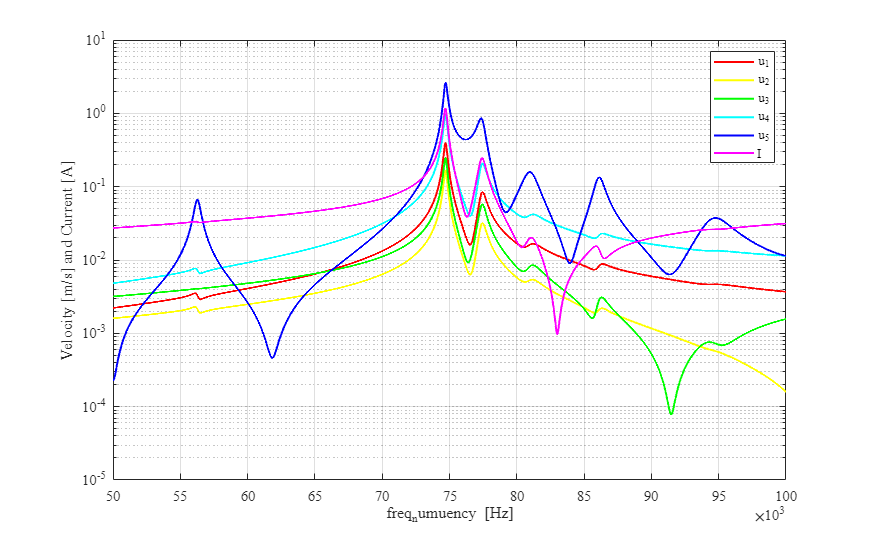

freq_num = 50e3:10:100e3;
uD_num_w = fr_uD_num(freq_num,interp1(freq_num, Z_p_w_steps,freq_num));
createfigure_fr(freq_num, abs(uD_num_w)',["u_1" "u_2" "u_3" "u_4" "u_5" "I"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

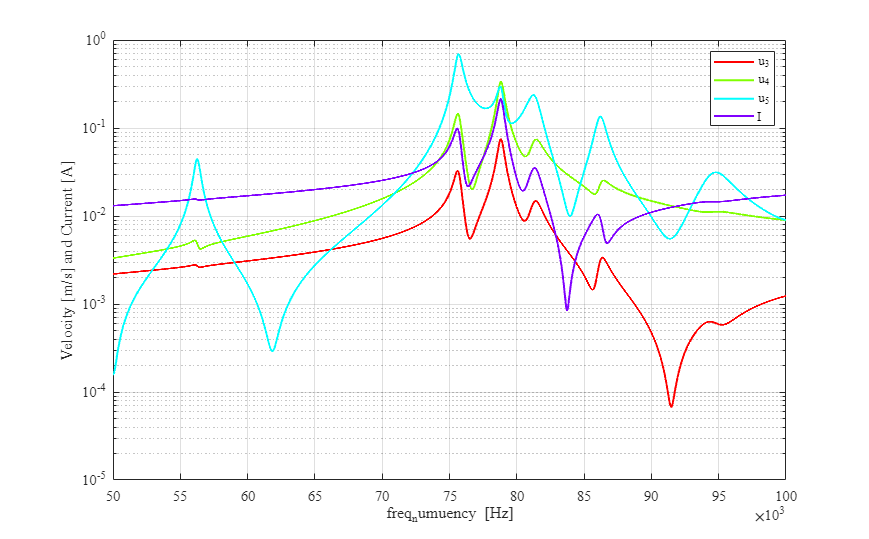

uDfronthalf_num_w = fr_uDfronthalf_num(freq_num,interp1(freq_num, Z_p_w_steps,freq_num));
createfigure_fr(freq_num, abs(uDfronthalf_num_w)',["u_3" "u_4" "u_5" "I"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

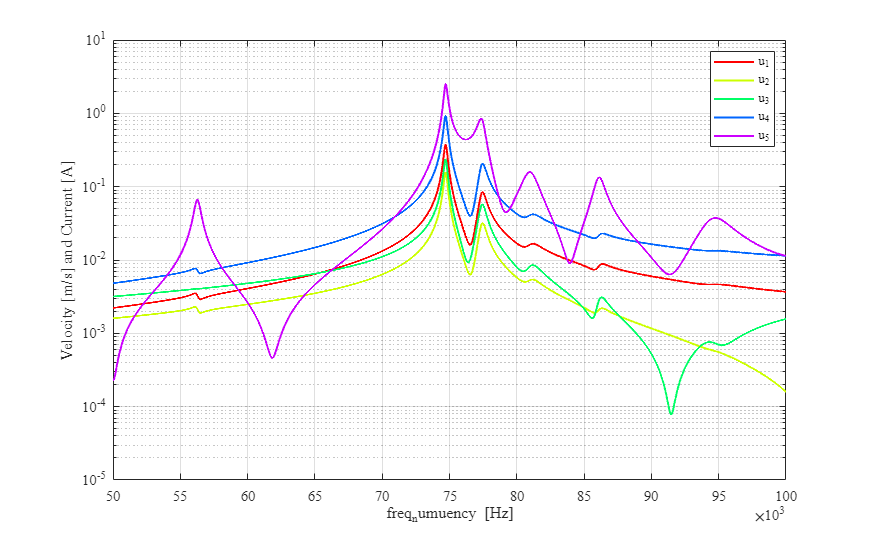

uE_num_w = fr_uE_num(freq_num,interp1(freq_num, Z_p_w_steps,freq_num));
createfigure_fr(freq_num, abs(uE_num_w)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

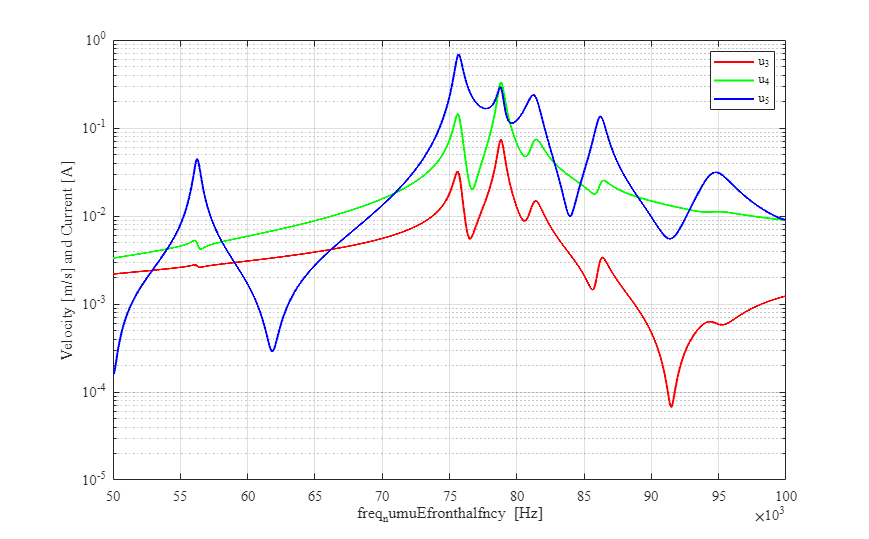

uEfronthalf_num_w = fr_uEfronthalf_num(freq_num,interp1(freq_num, Z_p_w_steps,freq_num));
createfigure_fr(freq_num, abs(uEfronthalf_num_w)',["u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

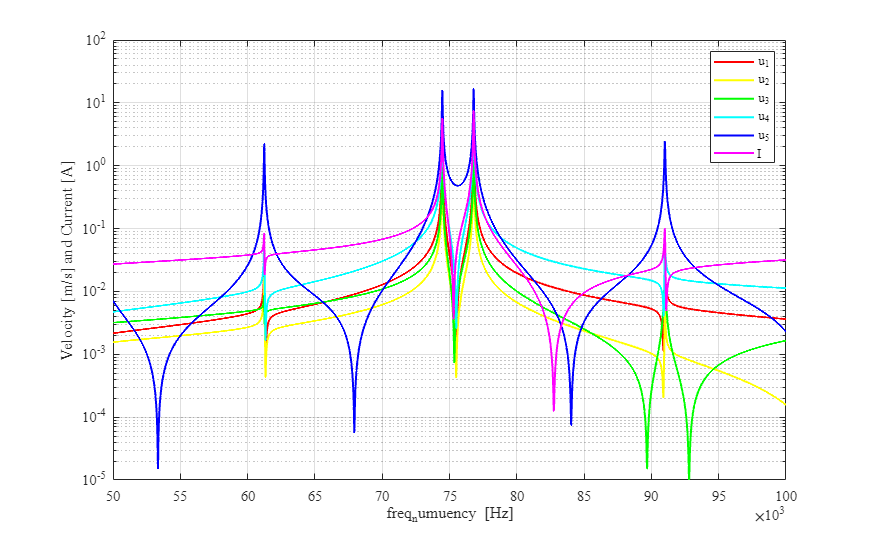

uD_num_wo = fr_uD_num(freq_num,interp1(freq_num, Z_p_wo_steps,freq_num));
createfigure_fr(freq_num, abs(uD_num_wo)',["u_1" "u_2" "u_3" "u_4" "u_5" "I"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

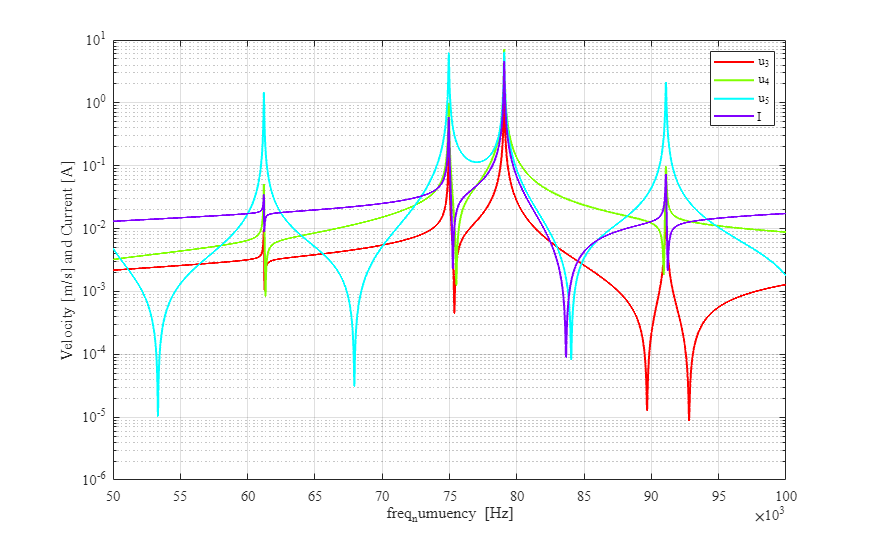

uDfronthalf_num_wo = fr_uDfronthalf_num(freq_num,interp1(freq_num, Z_p_wo_steps,freq_num));
createfigure_fr(freq_num, abs(uDfronthalf_num_wo)',["u_3" "u_4" "u_5" "I"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

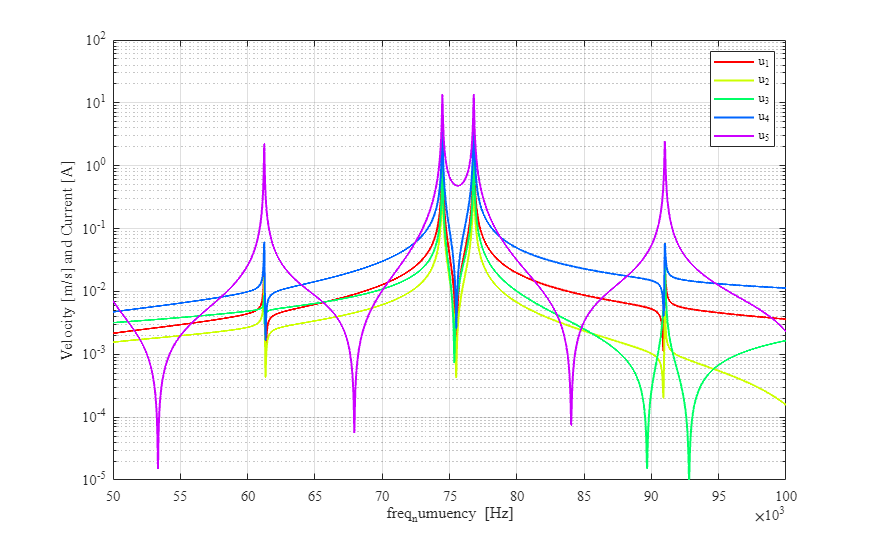

uE_num_wo = fr_uE_num(freq_num,interp1(freq_num, Z_p_wo_steps,freq_num));
createfigure_fr(freq_num, abs(uE_num_wo)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

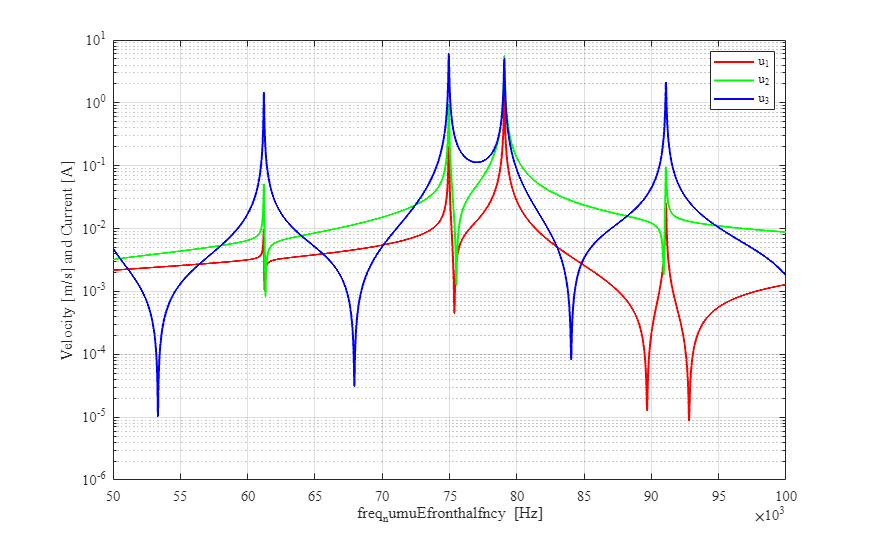

uEfronthalf_num_wo = fr_uEfronthalf_num(freq_num,interp1(freq_num, Z_p_wo_steps,freq_num));
createfigure_fr(freq_num, abs(uEfronthalf_num_wo)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s] and Current [A]","linear","log")

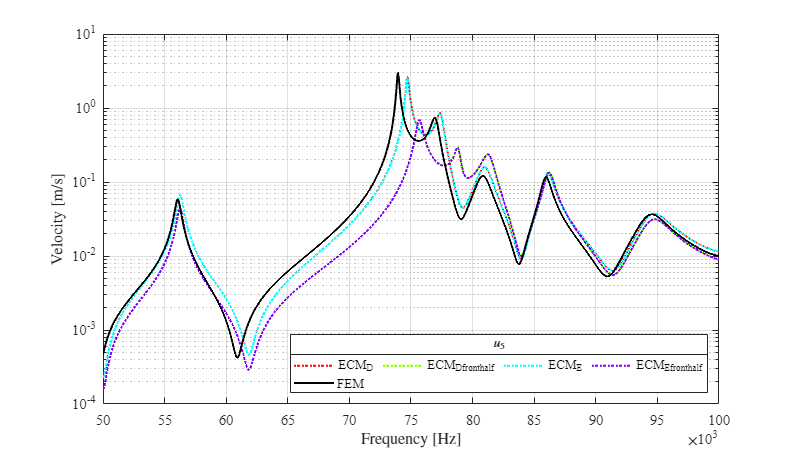

u_OBS_w     = import_COMSOL('D -230725 - OBS rework by WJ w. Steps.txt');
createfigure_fr_comp3(freq_num, ...
    [abs(uD_num_w(nCount,:)); ...
    abs(uDfronthalf_num_w(nCount-2,:)); ...
    abs(uE_num_w(nCount,:)); ...
    abs(uEfronthalf_num_w(nCount-2,:))]', ...
    u_OBS_w.freq, u_OBS_w.v5, ...
    'southeast',"$u_5$",["ECM_D" "ECM_{Dfronthalf}" "ECM_E" "ECM_{Efronthalf}"],"FEM", ...
    'Frequency $\left[\mathrm{Hz}\right]$','Velocity $\left[\mathrm{m/s}\right]$','linear','log')

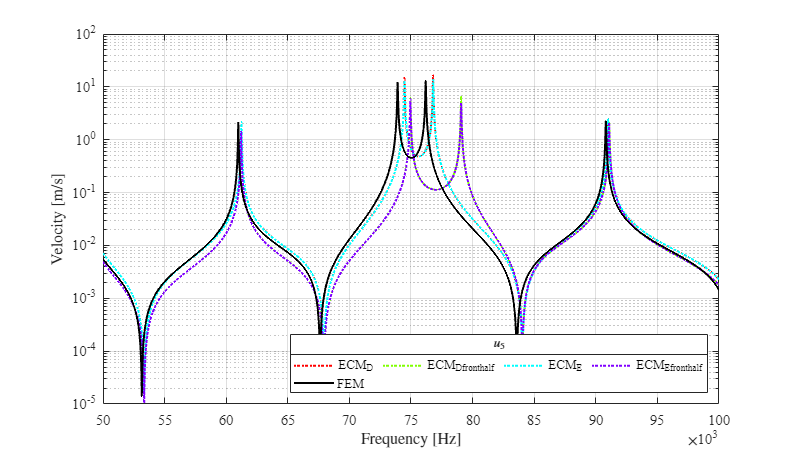

u_OBS_wo    = import_COMSOL('D -230725 - OBS rework by WJ w.o. Steps.txt');
createfigure_fr_comp3(freq_num, ...
    [abs(uD_num_wo(nCount,:)); ...
    abs(uDfronthalf_num_wo(nCount-2,:)); ...
    abs(uE_num_wo(nCount,:)); ...
    abs(uEfronthalf_num_wo(nCount-2,:))]', ...
    u_OBS_wo.freq, u_OBS_wo.v5, ...
    'southeast',"$u_5$",["ECM_D" "ECM_{Dfronthalf}" "ECM_E" "ECM_{Efronthalf}"],"FEM", ...
    'Frequency $\left[\mathrm{Hz}\right]$','Velocity $\left[\mathrm{m/s}\right]$','linear','log')

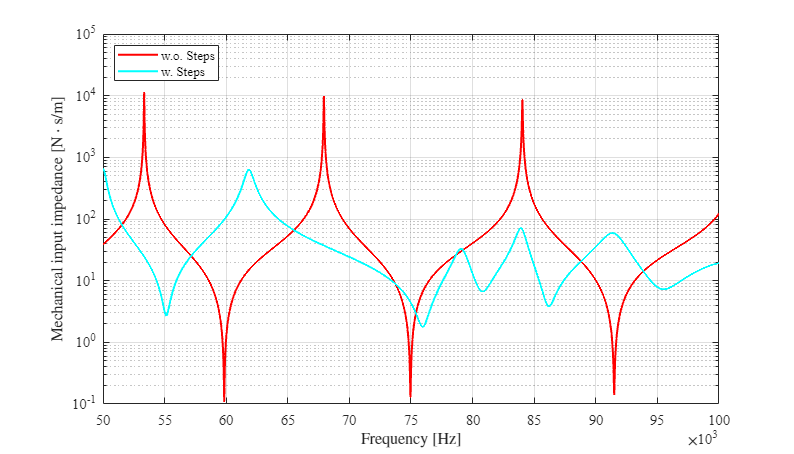

createfigure_fr2(freq_num, [abs(Z_p_wo_steps) abs(Z_p_w_steps)], ...
    'northwest',"",["w.o. Steps" "w. Steps"], ...
    'Frequency $\left[\mathrm{Hz}\right]$','Mechanical input impedance $\left[\mathrm{N}\cdot \mathrm{s/m}\right]$', ...
    'linear','log')